# 繪圖軟體應用 第15周(12/18)

# M_Map

## 1. Getting started

c 槽或是toolbox裡面要有m_map才可使用以下所有指令

m_proj(' ')

clear;clc

m_proj('oblique mercator'); %投影(斜麥卡托)
% m_coast;
% m_grid;

m_coast

m_proj('oblique mercator');
m_coast; %海岸線(xy軸不是經緯度)
% m_grid;

m_grid

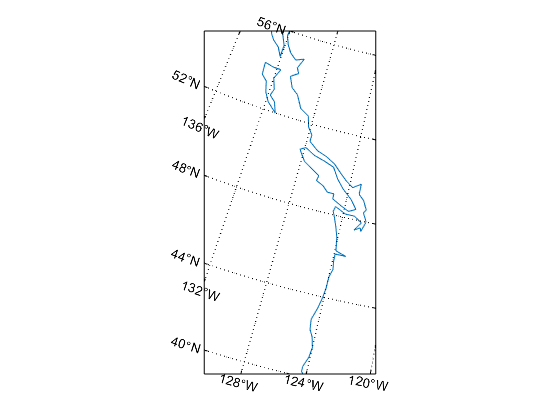

m_proj('oblique mercator');
m_coast;
m_grid;  %加上網格。反投影，加上經緯度

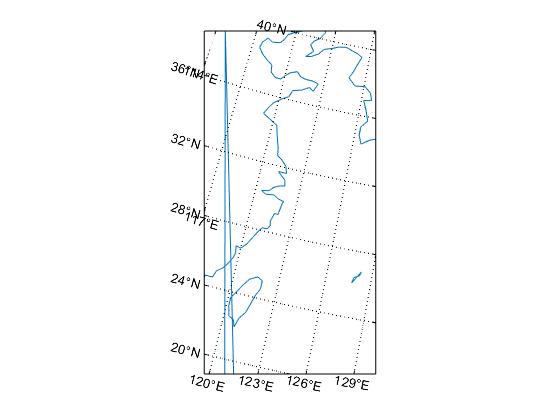

m_proj('oblique mercator','longitudes',[119.5 125], ...
           'latitudes',[40 20],'direction','vertical','aspect',.5)
m_coast;
m_grid;  %加上網格

This is a line map of the Oregon/British Columbia coast, using an Oblique Mercator projection (A few more complex maps can be generated by running the demo function `m_demo`).

% m_demo

## 2. Specifying projections

clear;clc
m_proj get     %get a list of the current projections,

Current mapping parameters -
 Projection: Mercator  (function: mp_cyl)
 longitudes: 100  140                    
 Latitudes: 10  30                       
 sphere: normal                          


m_proj('set'); %get a list of the current projections,

 
Available projections are:
     Stereographic
     Orthographic
     Azimuthal Equal-area
     Azimuthal Equidistant
     Gnomonic
     Satellite
     Albers Equal-Area Conic
     Lambert Conformal Conic
     Mercator
     Miller Cylindrical
     Equidistant Cylindrical
     Oblique Mercator
     Transverse Mercator
     Sinusoidal
     Gall-Peters
     Hammer-Aitoff
     Mollweide
     Robinson
     UTM


m_proj('set','Mercator') %使用麥卡托投影

     'Mercator'                            
     <,'lon<gitude>',( [min max] | center)>
     <,'lat<itude>',( maxlat | [min max]>  
     <,'sph<ere>', one of                  
         normal                            
         sphere                            
          grs80                            
          grs67                            
          wgs84                            
          wgs72                            
          wgs66                            
          wgs60                            
         clrk66                            
         clrk80                            
         intl24                            
         intl67                            


%details about the possible options for any of these projections,
% add its name to the above command

Which currently return the following list:

`Available projections are:`

`     Stereographic          `

`     Orthographic 正交`

`     Azimuthal Equal-area    `

`     Azimuthal Equidistant`

`     Gnomonic`

`     Satellite`

`     Albers Equal-Area Conic`

`     Lambert Conformal Conic`

`     Mercator 麥卡托`

`     Miller Cylindrical`

`     Equidistant Cylindrical`

`     Oblique Mercator 斜麥卡托`

`     Transverse Mercator`

`     Sinusoidal`

`     Gall-Peters`

`     Hammer-Aitoff`

`     Mollweide`

`     Robinson`

`     UTM`

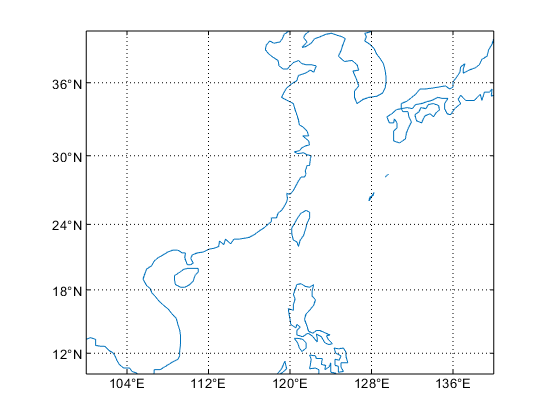

m_proj('Mercator','lon',[100 140],'lat',[10,40]);
clf
m_coast;
m_grid;

## 3. Coastlines and Bathymetry

**Coastline options**

help m_coast

  m_coast Add a coastline to a given map.
          m_coast draw a coastline as either filled patches (slow) or
          lines (fast) on a given projection. It uses a coastline database with
          a resolution of about 1/4 degree. 
 
          m_coast( (standard line option,...,...) )  or
          m_coast('line', (standard line option,...,...) ) draws the coastline
          as a simple line.
          m_coast('patch' ( ,standard patch options,...,...) ) draws the 
          coastline as a number of patches. 
 
     
          See also m_proj, m_grid



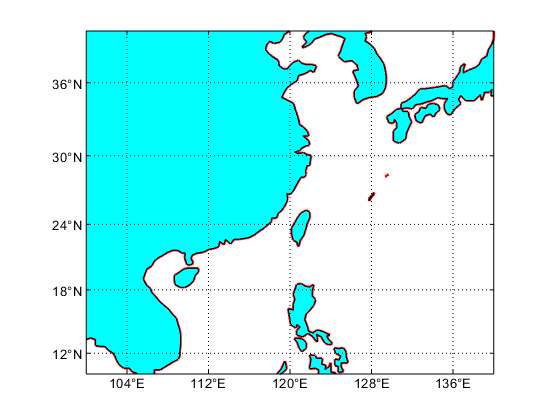


clear;clc
m_proj('Mercator','lon',[100 140],'lat',[10,40]);

m_coast('color','r','linewidth',2);  %海岸線顏色
m_coast('patch','c','edgecolor','k'); %陸地塗色、陸地邊界顏色
m_grid;

help m_hatch

  m_hatch Draws hatched or speckled interiors to a patch
        
     m_hatch(LON,LAT,STYL,ANGLE,STEP,...line parameters);
 
  INPUTS:
      X,Y - vectors of points.
      STYL - style of fill
      ANGLE,STEP - parameters for style
 
      E.g.
                  
       'single',45,5  - single cross-hatch, 45 degrees,  5 points apart 
       'cross',40,6   - double cross-hatch at 40 and 90+40, 6 points apart
       'speckle',7,1  - speckled (inside) boundary of width 7 points, density 1
                                (density >0, .1 dense 1 OK, 5 sparse)
       'outspeckle',7,1 - speckled (outside) boundary of width 7 points, density 1
                                (density >0, .1 dense 1 OK, 5 sparse)
 
      
       H=m_hatch(...) returns handles to hatches/speckles.
 
       [XI,YI,X,Y]=MHATCH(...) does not draw lines - instead it returns
       vectors XI,YI of the hatch/speckle info, and X,Y of the original
       outline mod

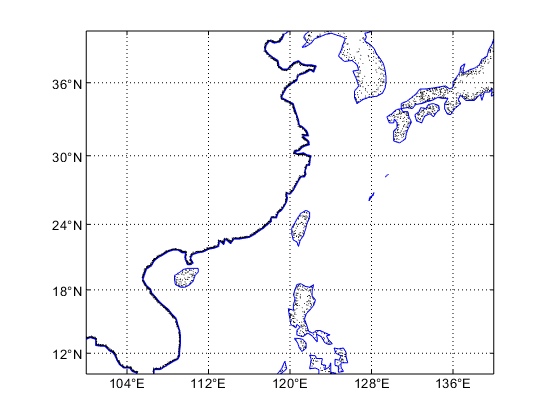

clf
m_coast('speckle','color','k'); %陸地以顆粒填色
m_coast('color','b');
m_grid;

**Topography/Bathymetry options**

`m_elev;`

Different levels can also be specified:

`m_elev('contour',LEVELS, optional contour arguments);`

For example, if you want all the contours to be dark blue, use:

`m_elev('contour',LEVELS,'edgecolor','b');`

Filled contours are also possible:

`m_elev('contourf',LEVELS, optional contourf arguments);`

help m_elev

  m_elev Contour elevation onto a map using a 1-degree database
         m_elev contours elevations at 1000m intervals for the map.
         m_elev(OPTN) where OPTN is one of the following strings lets
         you draw a particular background:
         OPTN: 'contour' -  contour lines are drawn.
               'contourf' -  filled contours are drawn. 
                                LEVELS are the levels used, and ARGS
                                are optional patch arguments of line types, 
                                colors, etc. 
               'pcolor'    - pcolor call
               'image'     - displays pixellated image
               'shadedrelief' - shaded relief map.
         m_elev(OPTN,args,...) lets you pass arguments to the OPTN call.
 
         [CS,H]=m_elev(...) allows access to the return arguments of the
         contour/contourf call.
 
         [ELEV,LONG,LAT]=m_elev

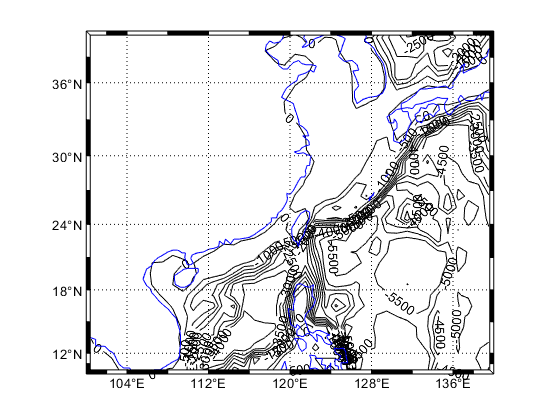

clear;clc;clf
% figure(1)
m_proj('Mercator','lon',[100 140],'lat',[10 40]);
[c,h] = m_elev('contour',[-7000:500:0],'edgecolor','k');
clabel(c,h);
m_coast('color','b');
m_grid('box','fancy'); %黑白間隔座標軸

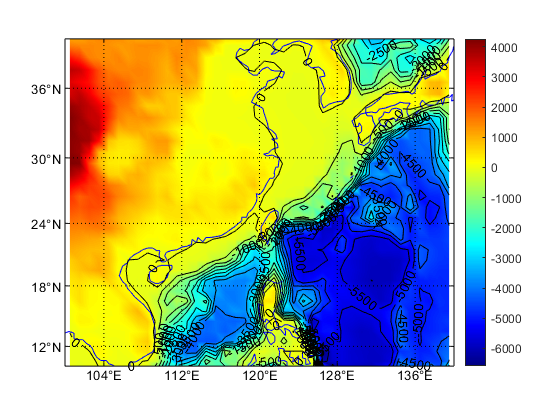

clear;clc;clf
% figure(2)
m_proj('Mercator','lon',[100 140],'lat',[10 40]);
m_elev('pcolor');
shading interp;
m_coast('color','b');
colormap('jet');
colorbar('v');
[c,h] = m_elev('contour',[-7000:500:0],'edgecolor','k');
clabel(c,h);
m_grid();

## 4. Customizing axes

help m_grid

  m_grid make a grid on a map.
         m_grid('parameter','value',...) with any number (or no)
         optional parameters is used to draw a lat/long grid for a
         previously initialized map projection.
 
         The optional parameters allow the user
         to control the look of the grid. These parameters are listed
         by m_grid('get'), with default parameters in m_grid('set');
 
         see also m_proj



m_grid('get');

      'axes',( gca | axis handle)
      'box',( 'on' | 'fancy' | 'off' )
      'xtick',( num | [value1 value2 ...])
      'ytick',( num | [value1 value2 ...])
      'xticklabels',[label1;label2 ...]
      'yticklabels',[label1;label2 ...]
      'xlabeldir', ( 'middle' | 'end' )
      'ylabeldir', ( 'end' | 'middle' )
      'ticklength',value
      'tickdir',( 'in' | 'out' )
      'tickstyle',('dm' | 'da' | 'dd'  )
      'color',colorspec
      'gridcolor',colorspec
      'backgroundcolor',colorspec
      'linewidth', value
      'linestyle', ( linespec | 'none' )
      'fontsize',value
      'fontname',name
      'XaxisLocation',( 'bottom' | 'middle' | 'top' ) 
      'YaxisLocation',( 'left' | 'middle' | 'right' ) 


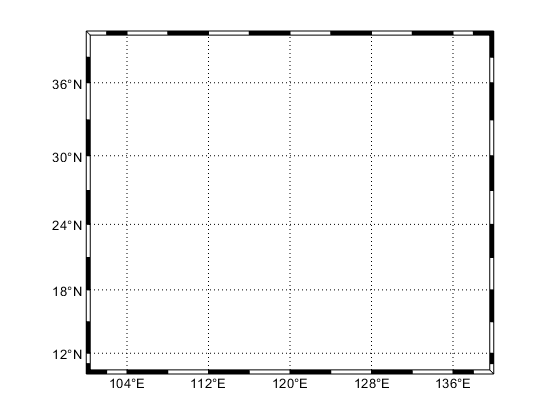

m_grid('box','fancy'); %黑白間隔座標軸

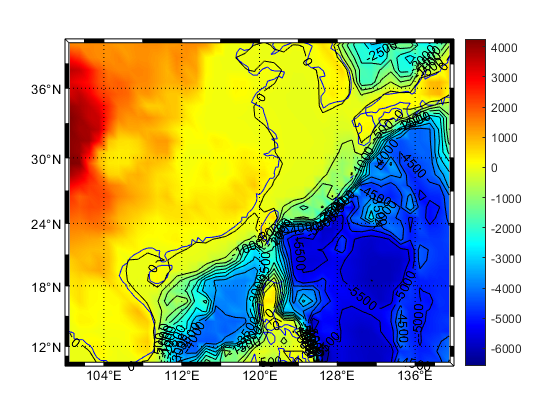

clear;clc;clf
m_proj('Mercator','lon',[100 140],'lat',[10 40]);
m_elev('pcolor');
shading interp;
m_coast('color','b');
colormap('jet');
colorbar('v');
[c,h] = m_elev('contour',[-7000:500:0],'edgecolor','k');
clabel(c,h);
m_grid('box','fancy');

Axis labels can be produced either in decimal degrees (`'dd'`) or degrees-minutes (`'dm'`, default). The `'da'` option is an abbreviated degrees-minutes format without degree marks or the N/S/E/W letters appended:

`  'tickstyle',( 'dd' | 'da' |  'dm' )`

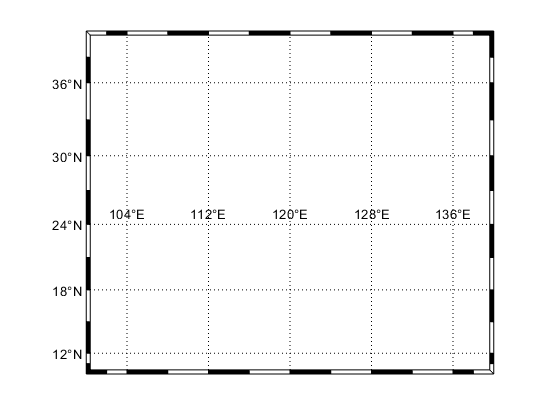

clf
m_grid('box','fancy','XaxisLocation','middle');

clear;clc;clf
m_proj('Mercator','lon',[100 140],'lat',[10 40]);
m_elev('pcolor');
shading interp;
m_coast('color','b');
colormap('jet');
colorbar('v');
[c,h] = m_elev('contour',[-7000:500:0],'edgecolor','k');
clabel(c,h);
m_grid('box','fancy');

%text([110,20],'Hainan') 無法用
[LAT,LON] = m_ll2xy(110,20) %在沒有grid()之前的xy座標

LAT = -0.1745

LON = 0.3564

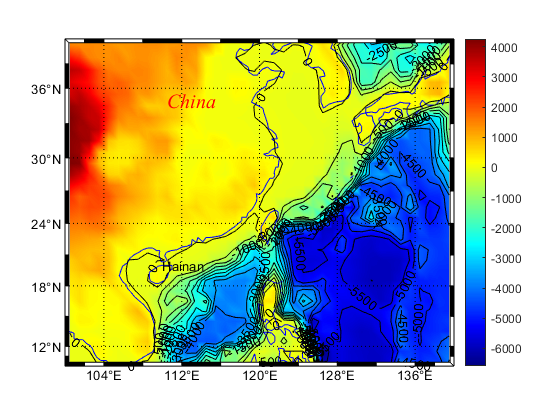

text(LAT,LON,'Hainan');

m_text(110,35,'\it China','color','r','FontSize',15,'FontName','times')

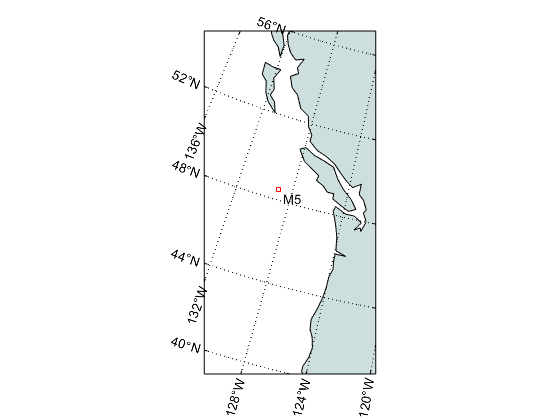

clf 
m_proj('oblique mercator');
m_coast('patch',[0.8 0.87 0.87]);
m_grid('xlabeldir','end','fontsize',10);
m_line(-129,48.5,'marker','square','markersize',4,'color','r');
m_text(-129,48.5,' M5','vertical','top');

## 5. Adding your own data

**Drawing lines, text, arrows, patches, hatches, speckles and contours**

`m_plot(LONG,LAT,...line properties)      `

`% draw a line on a map (erase current plot) `

`m_line(LONG,LAT,...line properties)      `

`% draw a line on a map `

`m_text(LONG,LAT,'string')                % Text   `

`m_quiver(LONG,LAT,U,V,S)                 % A quiver plot `

`m_patch(LONG,LAT,..patch properties)     % Patches.  `

`m_annotation('line',LON,LAT)             % Annotation`

help m_hatch

  m_hatch Draws hatched or speckled interiors to a patch
        
     m_hatch(LON,LAT,STYL,ANGLE,STEP,...line parameters);
 
  INPUTS:
      X,Y - vectors of points.
      STYL - style of fill
      ANGLE,STEP - parameters for style
 
      E.g.
                  
       'single',45,5  - single cross-hatch, 45 degrees,  5 points apart 
       'cross',40,6   - double cross-hatch at 40 and 90+40, 6 points apart
       'speckle',7,1  - speckled (inside) boundary of width 7 points, density 1
                                (density >0, .1 dense 1 OK, 5 sparse)
       'outspeckle',7,1 - speckled (outside) boundary of width 7 points, density 1
                                (density >0, .1 dense 1 OK, 5 sparse)
 
      
       H=m_hatch(...) returns handles to hatches/speckles.
 
       [XI,YI,X,Y]=MHATCH(...) does not draw lines - instead it returns
       vectors XI,YI of the hatch/speckle info, and X,Y of the original
       outline mod

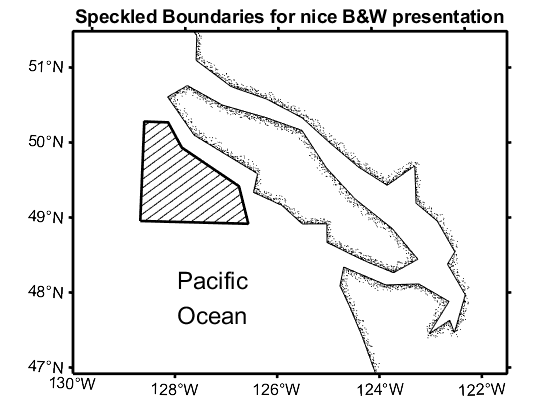

bndry_lon=[-128.8 -128.8 -128.3 -128 -126.8 -126.6 -128.8];
bndry_lat=[49      50.33  50.33  50   49.5   49     49];
    
clf;
m_proj('lambert','long',[-130 -121.5],'lat',[47 51.5],'rectbox','on');

m_coast('color','k');              % Coastline...
m_coast('speckle','color','k');    % with speckle added

m_line(bndry_lon,bndry_lat,'linewi',2,'color','k');     % Area outline ...
m_hatch(bndry_lon,bndry_lat,'single',30,5,'color','k'); % ...with hatching added.

m_grid('linewi',2,'linest','none','tickdir','out','fontsize',12);
title('Speckled Boundaries for nice B&W presentation','fontsize',14);
m_text(-128,48,{'Pacific','Ocean'},'fontsize',18);

**Drawing images and pcolor**

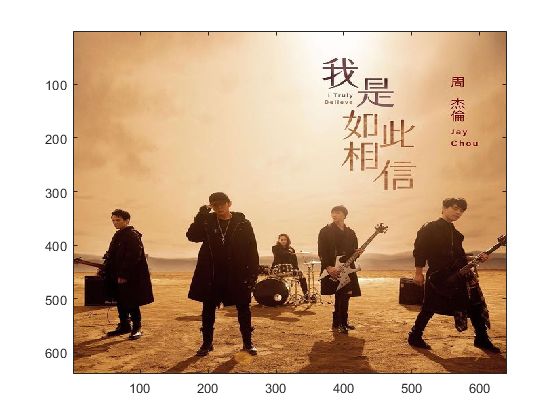

imm = imread('75472268.jpg');
figure
image(imm)


clf
m_proj('lambert','lat',[5 24],'long',[105 125]);

set(gcf,'color','w')   % Set background colour before m_image call

caxis([-6000 0]);
colormap(flipud([flipud(m_colmap('blues',10));m_colmap('jet',118)]));
m_etopo2('shadedrelief','gradient',3);

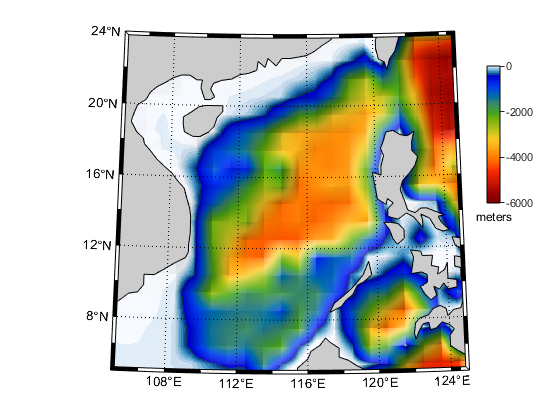

 
m_coast('patch',[.8 .8 .8]);
 
m_grid('box','fancy');

ax=m_contfbar(.97,[.5 .9],[-6000 0],[-6000:100:000],'edgecolor','none','endpiece','no');
xlabel(ax,'meters','color','k');